# 创建一个C_SW40 TB模型并拟合参数

https://doi.org/10.1103/PhysRevB.101.155427

## 创建一个C_SW40TB模型并拟合参数

Si = HR.from_POSCAR_SE('POSCAR_SW40',...
'WAN_NUM',40,...
'Type','mat',...
'alpharule',2,...
'onsite',false,...
'search_range' ,[2 2 0],...
'r_max',10,...
'Rd',1.426,...
'overlap',true,...
'level_cut',-1);

Generating 40/40 th orb nn information ...
Giving nn_level for 4672/4672 th hopping  ...
Generating Symbolic Hopping term ...< ok >
Setting NRPT 11/11 ...
applying alpha rule ...
the   1 th Rnn vector:  1.3740 Angstrom
the   2 th Rnn vector:  1.3850 Angstrom
the   3 th Rnn vector:  1.3950 Angstrom
the   4 th Rnn vector:  1.4030 Angstrom
the   5 th Rnn vector:  1.4060 Angstrom
the   6 th Rnn vector:  1.4090 Angstrom
the   7 th Rnn vector:  1.4120 Angstrom
the   8 th Rnn vector:  1.4250 Angstrom
the   9 th Rnn vector:  1.4320 Angstrom
the  10 th Rnn vector:  1.4390 Angstrom
the  11 th Rnn vector:  1.4440 Angstrom
the  12 th Rnn vector:  1.4580 Angstrom
the  13 th Rnn vector:  1.4600 Angstrom
the  14 th Rnn vector:  1.4690 Angstrom
the  15 th Rnn vector:  1.4710 Angstrom
the  16 th Rnn vector:  2.2740 Angstrom
the  17 th Rnn vector:  2.2910 Angstrom
the  18 th Rnn vector:  2.3120 Angstrom
the  19 th Rnn vector:  2.3290 Angstrom
the  20 th Rnn vector:  2.3420 Angstrom
the  21 th Rnn vector

$$\left(\begin{array}{cc} {\mathrm{VppP}}_{1} & \alpha_{1,\mathrm{VppP},1} \end{array}\right)$$

$$\left(\begin{array}{cc} {\mathrm{SppP}}_{1} & \alpha_{1,\mathrm{SppP},1}^{2} \end{array}\right)$$

          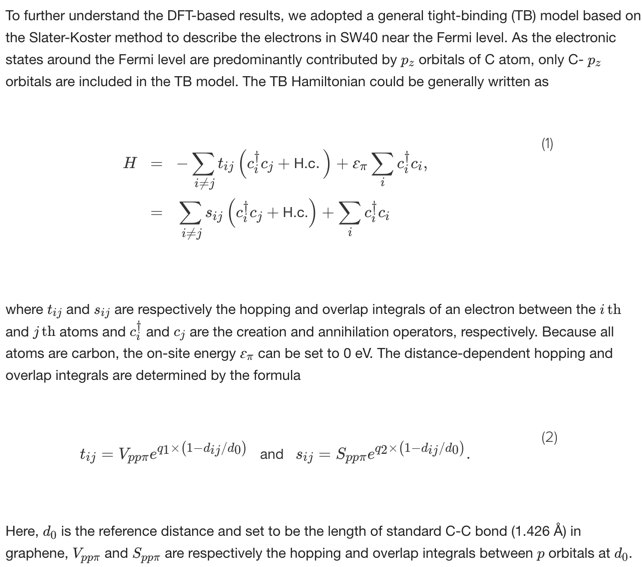

     ssS           *spS*  ppS      ppP  *sdS*         pdS     pdP    *ddS*  *ddP*   *ddD* 

*V*  -1.821  2.251  1.877  -0.126  0.342  1.144  -0.367  2.319  0.992  -0.060 

*q*  4.124  3.335  2.602  4.578  8.577  7.137  7.765  4.010  1.959  1.402 

S  0.105  -0.193  -0.222  0.151  0.244  0.225  -0.193  0.195  -0.059  0.093 

*q*  4.293  3.112  2.298  3.052  2.377  2.093  3.336  2.518  3.825  2.393 

 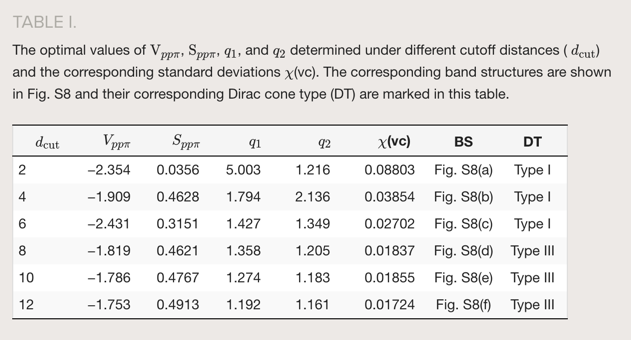

 -2.022  　  　  9.533  　  　   18.811  　  　  　 

### 赋值

Vhopping = Si.symvar_list

$$Vhopping = \left(\begin{array}{cc} {\mathrm{VppP}}_{1} & \alpha_{1,\mathrm{VppP},1} \end{array}\right)$$

Soverlap = symvar(Si.ScoeL)

$$Soverlap = \left(\begin{array}{cc} {\mathrm{SppP}}_{1} & \alpha_{1,\mathrm{SppP},1}^{2} \end{array}\right)$$

E_onsite  = [ ];
Vhopping_n = [-1.789];
Valpha_n = [1.274];
Soverlap_n = [0.4913];
Salpha_n = [1.161];

Si_n = Si.subs(Vhopping,[E_onsite,Vhopping_n,Valpha_n],Soverlap,[Soverlap_n,Salpha_n]);
%Si_n = Si.subs(Vhopping,[E_onsite,Vhopping_n,Valpha_n]);


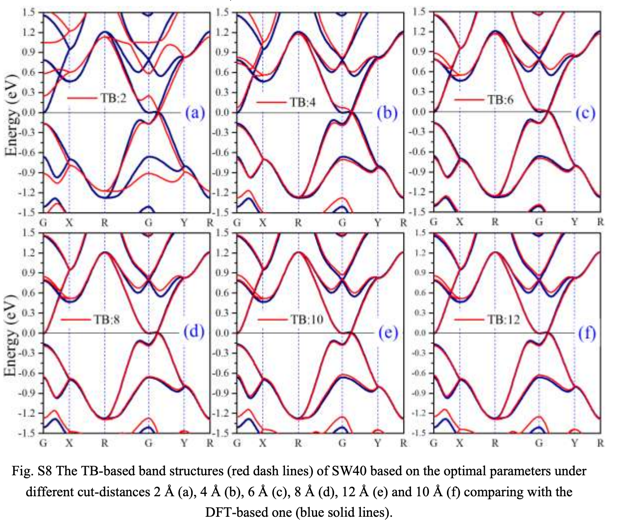

Si_n = Si_n < 'KPOINTS_SW40';
EIGENCAR = Si_n.EIGENCAR_gen();

BAND caculating 100/100 ...


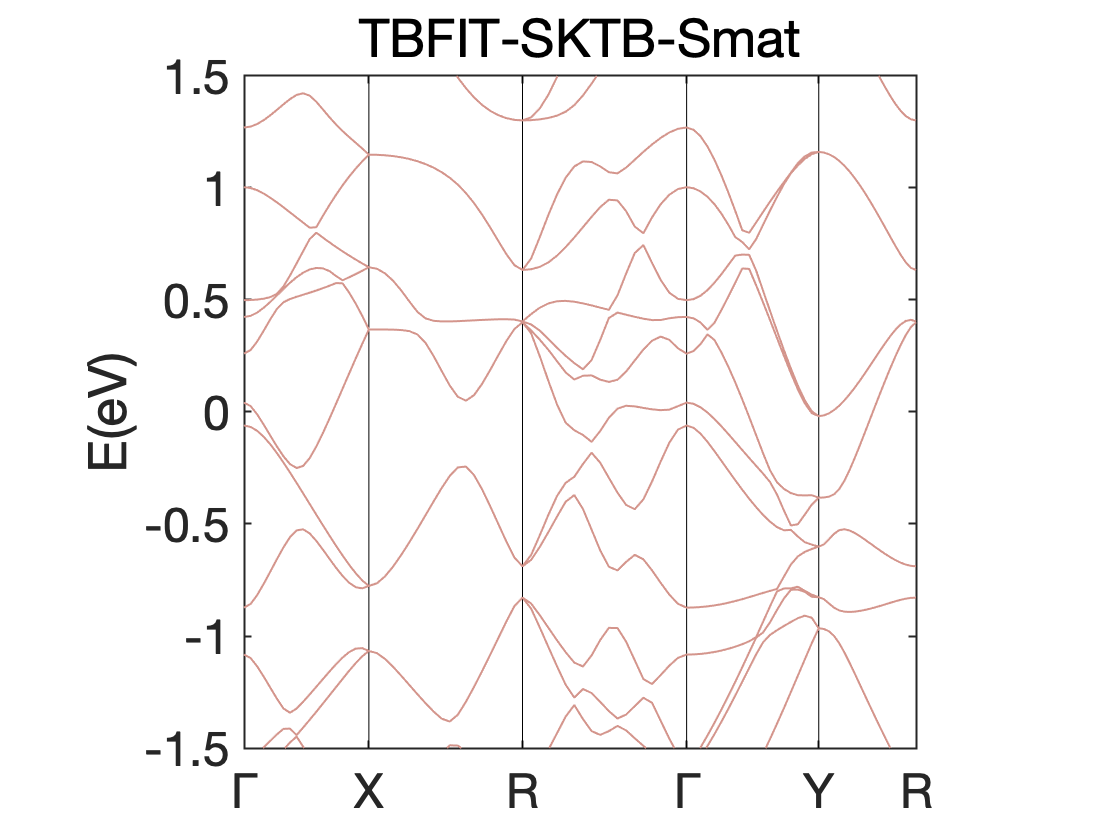

bandplot(EIGENCAR,[-1.5,1.5],'KPOINTS','KPOINTS_SW40','POSCAR','POSCAR_SW40');